clear all;
clc;
close all;

system=ElasticRoboticSystem();

st=system.getSamplingPeriod;

cs=ControlledSystemScara(system,'Alfa');


## Open loop

Definisco la portante come un segnale sinusoidale a bassa frequenza, con un'ampiezza tale da non sforare i limiti. L'ideale è andare in prossimità dei limiti mantenendo un discreto margine (esempio 70% limiti).

omega_portante=0.05;
ampiezza_portante=0.5;
T_portante=2*pi/omega_portante;

scelgo una lunghezza dell'esperimento di almeno un periodo della portante.

t=(0:st:(1.1*T_portante))';
portante=ampiezza_portante*sin(omega_portante*t);

Dopo di che posso andare a definire il segnale eccitante, che partirà da una frequenza maggiore (almeno un decade).

w0=omega_portante*30; %rad/s
w1=pi/st; %rad/s
control_action_identificazione = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');
ampliezza_identificazione=2;

Sommo i due segnali

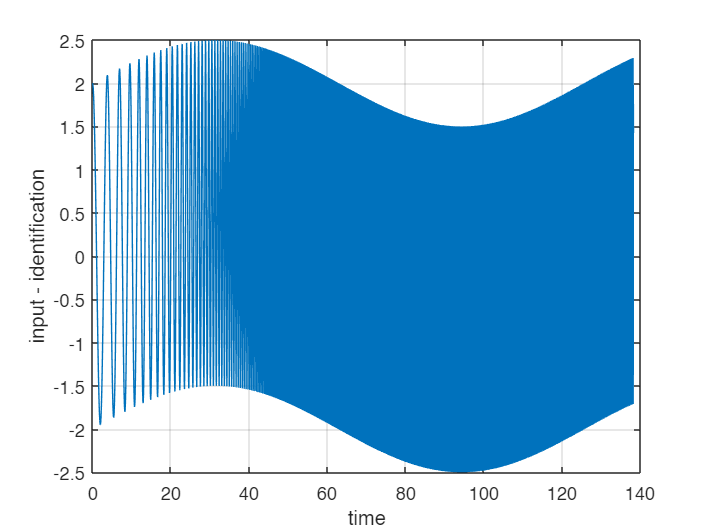

control_action=portante + control_action_identificazione*ampliezza_identificazione;
figure
plot(t,control_action)
xlabel('time')
ylabel('input - identification')
grid on

## Simulazione sistema

I tratti con velocità vicina allo 0 hanno una dinamica chiaramente non lineare, l'approssimazione lineare nelle frequenze esplorare dal segnale eccitante in quei punti sarà scarsa.

cs.initialize
tic
for idx=1:length(t)
    [process_output(idx,:),t(idx,1)]=cs.openloop(control_action(idx));
end
toc


figure(1)
subplot(2,1,1)
plot(t,process_output(:,2))
xlabel('time')
ylabel('output - velocità motore')
grid on

subplot(2,1,2)
plot(t,control_action)
xlabel('time')
ylabel('input - coppia motore')
grid on

Nota: le frequenze in prossimità dei cambi di velocità sono stimate peggio (è opportuno che: 1) ripetere con segnali diversi 2) in validazione il signale sia diverso).

## Identificazione

### Calcolo risposta in frequenza

Definisco l'oggetto identification data (iddata)

identification=iddata(process_output(:,2),control_action,st);

Calcolo la risposta in frequenza con il comando e la plotto

freq_resp_ident = spafdr(identification);
figure(2)
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(freq_resp_ident, bode_opts);
grid on
hold on

Plotto la frequenza di inizio del segnale eccitante

hold on
plot(w0*[1 1],ylim,'--r')
hold off
grid on

La parte a sinistra nella linea tratteggiate non mi interessa (il segnale non ha contribuito informatico apprezzabile ed è "disturbato" dalla presenza dell'attrito statico).

### Stima del modello

devo dire al modello di non considerare le basse frequenze. Creo un vettore di pesi da dare allo stimatore (peso basso, poca importanza).

peso=ones(length(freq_resp_ident.Frequency),1);
wpeso0=10;
wpeso1=2000;
peso(freq_resp_ident.Frequency<wpeso0)=1e-5;
peso(freq_resp_ident.Frequency>wpeso1)=1e-5;

opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
modello_continuo = ssest(freq_resp_ident,3,opts);
modello_discreto = ssest(freq_resp_ident,3,'Ts',st,opts);

## Identificazione

Definisco segnale di identificazione

#### Portante

omega_portante=0.1;
ampiezza_portante=30;
T_portante=2*pi/omega_portante;
t=(0:st:(1.1*T_portante))';
portante=ampiezza_portante*sin(omega_portante*t);

#### Segnale eccitante

w0=1; %rad/s
w1=1000; %rad/s
control_action_identificazione = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');

ampliezza_identificazione=80;

sommo

exciting_signal=zeros(length(t),system.getInputNumber);
exciting_signal(:,1)=portante+ control_action_identificazione*ampliezza_identificazione;

Simulo il sistema

cs.initialize % reinizializza la simulatione

cs.setRestTime(1); % attendi di stabilizzarti
cs.moveTo([0 0]); % cambia punto di lavoro

measure=system.computeOutput;

reference=zeros(length(t),6); % 2*(pos,vel,acc)
reference(:,1)=measure(1);
reference(:,2)=measure(2);

for idx=1:length(t)
        % step: simulo il sisteme in anello chiuso
        [process_output(idx,:),control_action(idx,:),t(idx,1)]=cs.step(reference(idx,:)',exciting_signal(idx,:)');  
        % ingresso 1: riferimento
        % ingresso 2: segnale a valle del controllore
end

figure(1)
subplot(3,2,1)
plot(t,process_output(:,1))
xlabel('time')
ylabel('position 1')
grid on

subplot(3,2,3)
plot(t,process_output(:,3))
xlabel('time')
ylabel('velocity 1')
grid on

subplot(3,2,5)
plot(t,control_action(:,1),'-b',t,exciting_signal(:,1),'--r')
xlabel('time')
ylabel('torque 1')
grid on

subplot(3,2,2)
plot(t,process_output(:,2))
xlabel('time')
ylabel('position 2')
grid on

subplot(3,2,4)
plot(t,process_output(:,4))
xlabel('time')
ylabel('velocity 2')
grid on

subplot(3,2,6)
plot(t,control_action(:,2),'-b',t,exciting_signal(:,2),'--r')
xlabel('time')
ylabel('torque 2')
grid on

Salvo i risultati

figure

experiment=iddata(process_output,control_action,st);
experiment.InputName=system.getInputName;
experiment.OutputName=system.getOutputName;
experiment_freqresp = spafdr(experiment);

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(experiment_freqresp, bode_opts);
grid on
hold on
hold on
plot(w0*[1 1],ylim,'--r')
hold off
grid on